# Curves defined implicitly by functions

Not every curve can be expressed in terms of an explicit function. Curves can also be expressed implicitly through relationships between variables. 

For example, the equation for a circle of radius 1, centered at the origin is $x^2 + y^2 -1 = 0$. The left-hand side of this equation can be thought of as a function of two variables, $f(x,y) = x^2 + y^2 -1$, and the set of points, $(x, y)$, where $f=0$ defines a curve, which we call the unit circle.

To evaluate functions of two variables in MATLAB, we'll use meshgrid.  Before you go on, you should [read about meshgrid in this article](https://www.mathworks.com/company/newsletters/articles/using-matlabs-meshgrid-command-and-array-operators-to-implement-one-and-two-variable-functions.html).

Here are the steps we'll follow to evaluate$f(x,y)$:

- We'll define **myfunc1** to take **x** and **y** as input variables and return **f(x, y)** as an output variable.

- We'll create a 1D matrix called x with a range of values along the x-axis, and a 1D matrix y with a range of values along the y-axis.

- We'll use meshgrid to create two 2D matrices, xgrid and ygrid.

- We'll use myfunc1 to evaluate f for all values in xgrid and ygrid.

As usual, we have to put all function definitions at the end, but here is a copy of myfunc1

**function res = myfunc1(x, y)**

**    res = x.^2 + y.^2 - 1;**

**end**

Notice that we have to use **.^**, which computes exponentiation elementwise.

Now we'll define **x** and **y**.

x = linspace(-1.2, 1.2, 121)

x =    -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.0400   -1.0200   -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200


y = x

y =    -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.0400   -1.0200   -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200


**meshgrid** is the first function we've seen that returns two output variables.  Here's how we use it.

[xgrid, ygrid] = meshgrid(x, y)

xgrid =    -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.0400   -1.0200   -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200
   -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.0400   -1.0200   -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200
   -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.0400   -1.0200   -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200
   -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.040

ygrid =    -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000
   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800
   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600   -1.1600
   -1.1400   -1.1400   -1.1400   -1.1400   -1.1400   -1.1400   -1.1400   -1.1400   -1.140

The first output variable gets assigned to **xgrid**, the second gets assigned to **ygrid**.

Now we can evaluate **myfunc1**

z = myfunc1(xgrid, ygrid)

z =     1.8800    1.8324    1.7856    1.7396    1.6944    1.6500    1.6064    1.5636    1.5216    1.4804    1.4400    1.4004    1.3616    1.3236    1.2864    1.2500    1.2144    1.1796    1.1456    1.1124    1.0800    1.0484    1.0176    0.9876    0.9584    0.9300    0.9024    0.8756    0.8496    0.8244
    1.8324    1.7848    1.7380    1.6920    1.6468    1.6024    1.5588    1.5160    1.4740    1.4328    1.3924    1.3528    1.3140    1.2760    1.2388    1.2024    1.1668    1.1320    1.0980    1.0648    1.0324    1.0008    0.9700    0.9400    0.9108    0.8824    0.8548    0.8280    0.8020    0.7768
    1.7856    1.7380    1.6912    1.6452    1.6000    1.5556    1.5120    1.4692    1.4272    1.3860    1.3456    1.3060    1.2672    1.2292    1.1920    1.1556    1.1200    1.0852    1.0512    1.0180    0.9856    0.9540    0.9232    0.8932    0.8640    0.8356    0.8080    0.7812    0.7552    0.7300
    1.7396    1.6920    1.6452    1.5992    1.5540    1.5096    1.4660    1.4232    1.3812   

## Finding zeros

Now we'd like to find the places where $f(x,y)$is 0.  The MATLAB function contour generates a contour plot, which shows the locations where the function has particular values.

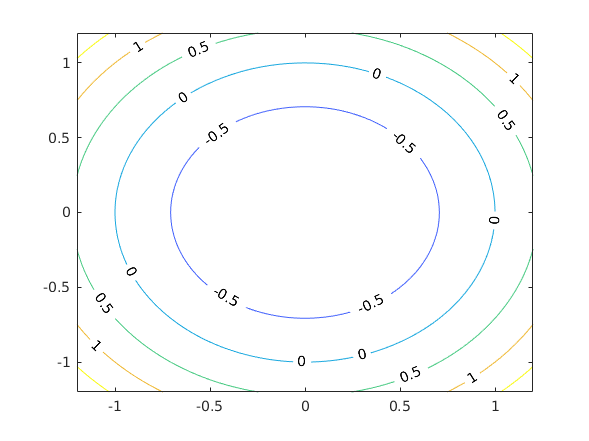

contour(xgrid,ygrid,z,'ShowText','on');

In this example, 0 is one of the values contour chooses automatically, but we can also specify the values we want.

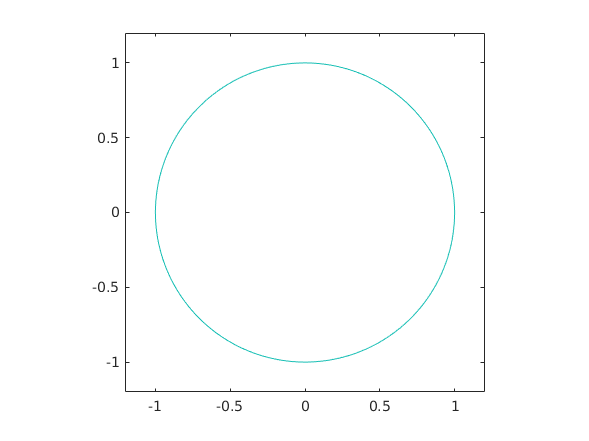

v = [0,0];
contour(xgrid,ygrid,z,v);
axis('equal')

By specifying that the axes should be equal, we make it clearer that the results form a circle.

We can use **contourc** to compute the locations where $f(x,y)$is 0 and return them in an array.  The result, C, is a ContourArray, which stores the results, in a matrix, in a weird format.  To unpack the values in this matrix, we'll use [matrix indexing, which you should read about in this article](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html).

C = contourc(x,y,z,v)

C =          0   -0.9800   -0.9798   -0.9755   -0.9707   -0.9656   -0.9600   -0.9539   -0.9474   -0.9404   -0.9400   -0.9329   -0.9249   -0.9200   -0.9165   -0.9075   -0.9000   -0.8980   -0.8879   -0.8800   -0.8772   -0.8660   -0.8600   -0.8541   -0.8416   -0.8400   -0.8284   -0.8200   -0.8146   -0.8000
  389.0000    0.1989    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3411    0.3600    0.3800    0.3918    0.4000    0.4200    0.4358    0.4400    0.4600    0.4749    0.4800    0.5000    0.5102    0.5200    0.5400    0.5425    0.5600    0.5723    0.5800    0.6000


level = C(1,1)

level = 0

numxy = C(2,1)

numxy = 389

xzero = C(1,2:end)

xzero =    -0.9800   -0.9798   -0.9755   -0.9707   -0.9656   -0.9600   -0.9539   -0.9474   -0.9404   -0.9400   -0.9329   -0.9249   -0.9200   -0.9165   -0.9075   -0.9000   -0.8980   -0.8879   -0.8800   -0.8772   -0.8660   -0.8600   -0.8541   -0.8416   -0.8400   -0.8284   -0.8200   -0.8146   -0.8000   -0.7846


yzero = C(2,2:end)

yzero =     0.1989    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3411    0.3600    0.3800    0.3918    0.4000    0.4200    0.4358    0.4400    0.4600    0.4749    0.4800    0.5000    0.5102    0.5200    0.5400    0.5425    0.5600    0.5723    0.5800    0.6000    0.6200


Now xzero and yzero contain corresponding values of x and y where $f(x,y)$is 0, and we can plot them.

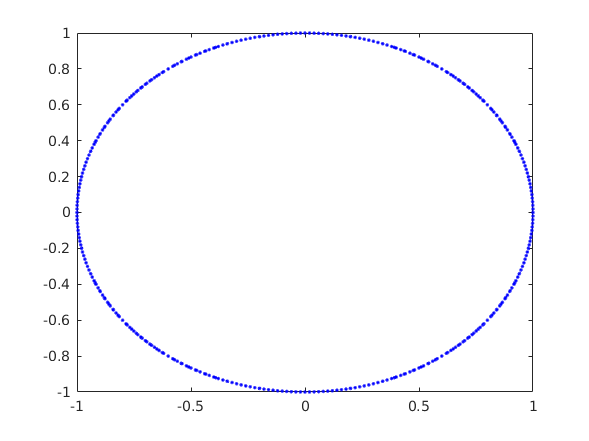

plot(xzero, yzero,'b.')

## Generalizing

There is no end to the functions of two variables that you can define. There is, however, a set of functions that show up again and again, and these are the quadratic functions of two variables. The general form (containing all possible quadratic, linear and constant terms) is


$$f(x,y) = A x^2+B x y + C y^2+D x + E y + F$$


where A,B,C,D,E,and F are arbitrary parameters, some of which may be zero. The curves defined by $f=0$ are called conic sections, and represent the intersection of a double cone and a plane. The non-degenerate cases include circles, parabolas, ellipses, and hyperbolas.

**Exercise 1**: Use **contour** to visualize solutions to the equation 


$$\frac{x^2}{a^2} + \frac{y^2}{b^2} - 1 = 0$$


for different values of **a** and **b**. What kind of curve do you get?  What features of the curve do $a$ and $b$ control?  Hint: Write a function called **myfunc2** that takes **x**, **y**, **a**, and **b** as input variables.  Use a for loop to plot contours for a range of values for **a**, with **b** held constant.

Use **contour** to visualize solutions to the equation 


$$\frac{x^2}{a^2} - \frac{y^2}{b^2} - 1 = 0$$
 

for different values of a and b. What kind of curve do you get?  What features of the curve do $a$ and $b$ control?

**Exercise 2**: Do some internet research to find out under what conditions the solutions of $f
$define an ellipse, a parabola, a hyperbola, or a circle. Visualize solutions for each of the conditions and confirm that they are correct.

## Function definitions

function res = myfunc1(x,y)
    % myfunc1   Computes f(x, y) = x^2 + y^2 -1
    res = x.^2 + y.^2 - 1;
end
